fun = @(x) exp(sin(x)+pi*cos(x))+exp(x);
acc=integral(fun, 0, 2*pi);
disp(acc)

  573.6148



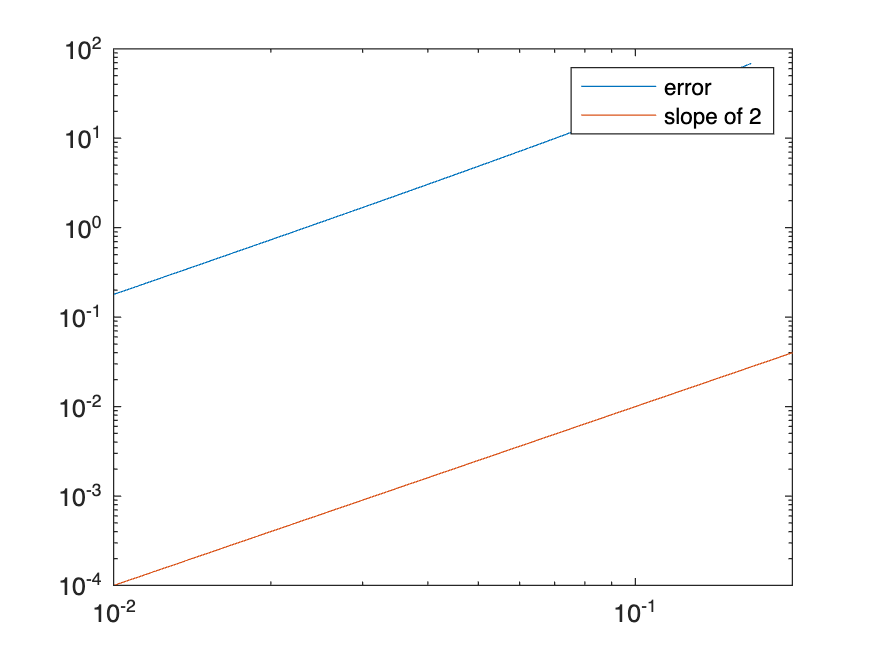


n_ary=5:100;
e_ary=zeros(1,length(n_ary));
for i =2:length(n_ary)
    n=n_ary(i);
    t_n=trap(n,fun);
    e_ary(i)=abs(t_n-acc);
end
h_ary=1./n_ary;
loglog(h_ary,e_ary);hold on
loglog(h_ary,h_ary.^2);
legend('error','slope of 2')
hold off

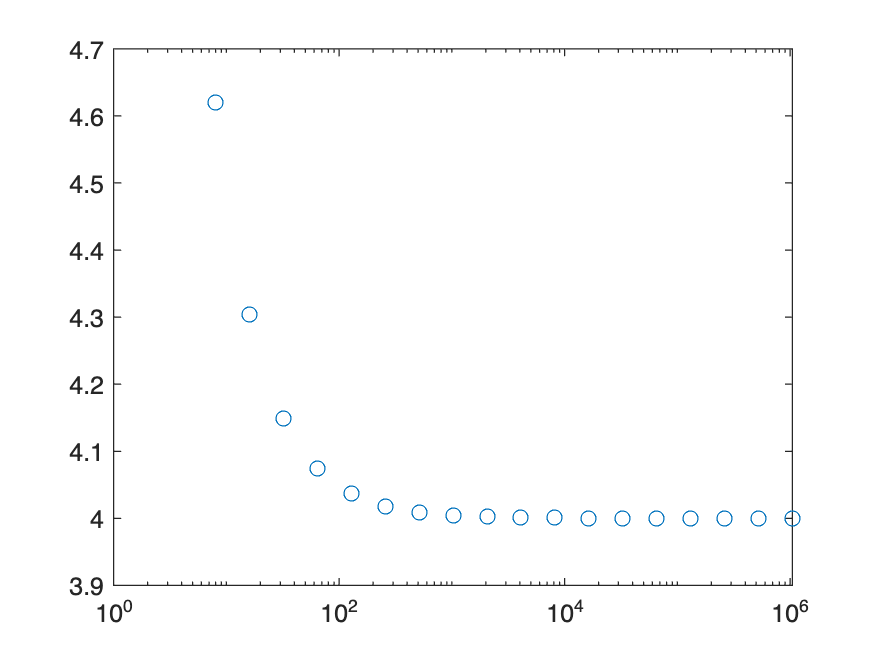

n_ary = 3:20;
n_ary = 2.^n_ary;
p_ary = zeros(1,length(n_ary));

for i = 1:length(n_ary)
    n = n_ary(i);
    t_n = trap(n,fun);
    t_2n = trap(2*n,fun);
    t_4n = trap(4*n,fun);

    p_ary(i) = (t_n-t_2n)/(t_2n-t_4n);
end
semilogx(n_ary,p_ary,'o');

function result = trap(n,f)

    x_ary = linspace(0,2*pi,n);
    h = 2*pi/(n-1);
    
    f_ary = f(x_ary);
    
    trap = sum(f_ary(2:end-1))*h;
    trap = trap + (f_ary(1)+f_ary(end))*h/2;

    result = trap;
end